% ejercicio2_from_wheels_con_3D.m
% Sustituye los 21 valores de ω_R y ω_L y añade simulación 3D sin eliminar
% ninguna de las gráficas existentes.

clear; close all; clc;

%% Parámetros y tiempo
r  = 0.05;      % radio de rueda [m]
L  = 0.18;      % distancia entre ejes [m]
dt = 1;        % paso de muestreo [s]
t  = (0:20)';  % instantes 0,1,...,20
N  = length(t);

%% Señales de entrada (ω_R y ω_L) – 21 valores
omega_R = [ ...
    4.582; 4.773; 5.291; 5.960; 6.490; ...
   -1.168; -1.364; 5.960; 5.291; 4.773; ...
    4.582; 4.773; 5.291; 5.960; 6.490; ...
    6.686; 6.490; 5.960; 5.291; 4.773; ...
    4.582 ];
omega_L = [ ...
    1.701; 2.353; 3.676; 4.856; 5.618; ...
   13.735; 13.472; 4.856; 3.676; 2.353; ...
    1.701; 2.353; 3.676; 4.856; 5.618; ...
    5.881; 5.618; 4.856; 3.676; 2.353; ...
    1.701 ];
assert(numel(omega_R)==N && numel(omega_L)==N,'ω_R y ω_L deben tener 21 valores');

%% Cinemática diferencial
v = r*(omega_R + omega_L)/2;   % velocidad lineal [m/s]
w = r*(omega_R - omega_L)/L;   % velocidad angular [rad/s]

%% Integración Euler para obtener pose
x   = zeros(N,1);
y   = zeros(N,1);
phi = zeros(N,1);
for k = 1:N-1
    phi(k+1) = phi(k) + w(k)*dt;
    x(k+1)   = x(k) + v(k)*cos(phi(k))*dt;
    y(k+1)   = y(k) + v(k)*sin(phi(k))*dt;
end

%% Tabla de resultados
T2 = table( ...
  t, v, w, omega_R, omega_L, x, y, rad2deg(phi), ...
  'VariableNames', ...
  {'t_s','v_m_s','omega_rad_s','omega_R','omega_L','x_m','y_m','theta_deg'});
disp(T2);

    t_s     v_m_s     omega_rad_s    omega_R    omega_L       x_m         y_m        theta_deg 
    ___    _______    ___________    _______    _______    _________    ________    ___________

     0     0.15707      0.80028       4.582      1.701             0           0              0
     1     0.17815      0.67222       4.773      2.353       0.15707           0         45.853
     2     0.22418      0.44861       5.291      3.676       0.28116     0.12783         84.368
     3      0.2704      0.30667        5.96      4.856       0.30316     0.35092         110.07
     4      0.3027      0.24222        6.49      5.618       0.21036      0.6049         127.64
     5     0.31418      -4.1397      -1.168     13.735 

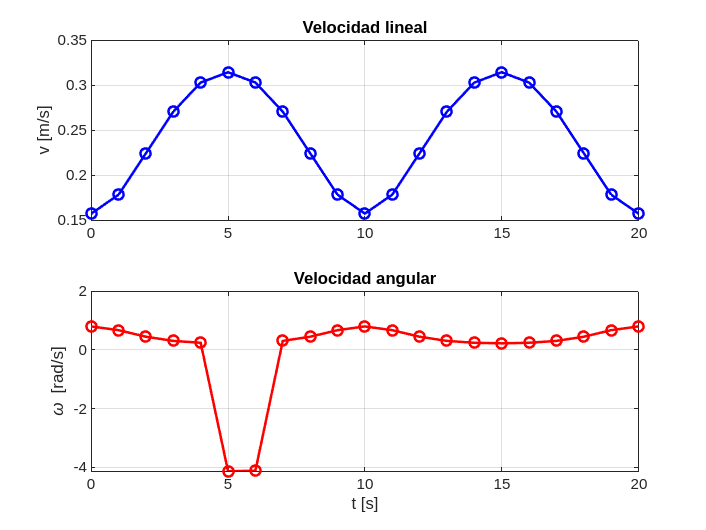


%% Gráfica v y ω
figure('Name','Velocidades','NumberTitle','off');
subplot(2,1,1)
plot(t, v,'b-o','LineWidth',1.5), grid on
ylabel('v [m/s]'), title('Velocidad lineal')
subplot(2,1,2)
plot(t, w,'r-o','LineWidth',1.5), grid on
xlabel('t [s]'), ylabel('\omega [rad/s]'), title('Velocidad angular')

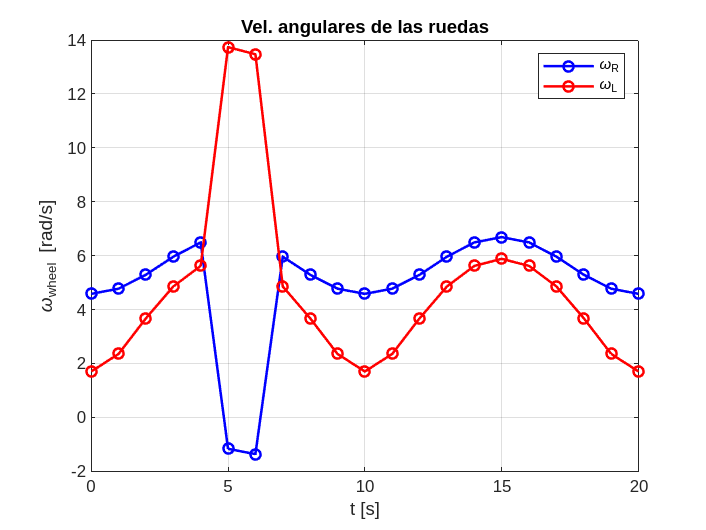


%% Gráfica de velocidades de rueda
figure('Name','Vel. angulares de rueda','NumberTitle','off');
plot(t, omega_R,'b-o', t, omega_L,'r-o','LineWidth',1.5), grid on
xlabel('t [s]'), ylabel('\omega_{wheel} [rad/s]')
legend('\omega_R','\omega_L'), title('Vel. angulares de las ruedas')

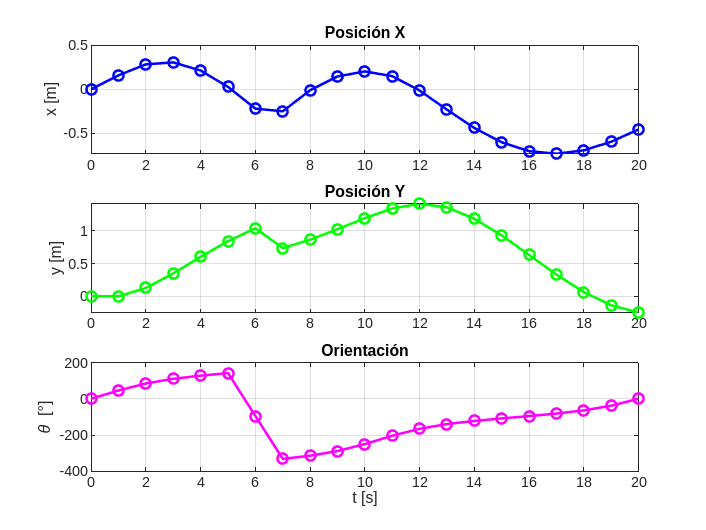


%% Gráficas de pose vs. tiempo
figure('Name','Pose vs. Tiempo','NumberTitle','off');
subplot(3,1,1)
plot(t, x,'b-o','LineWidth',1.5), grid on, ylabel('x [m]'), title('Posición X')
subplot(3,1,2)
plot(t, y,'g-o','LineWidth',1.5), grid on, ylabel('y [m]'), title('Posición Y')
subplot(3,1,3)
plot(t, rad2deg(phi),'m-o','LineWidth',1.5), grid on
xlabel('t [s]'), ylabel('\theta [°]'), title('Orientación')

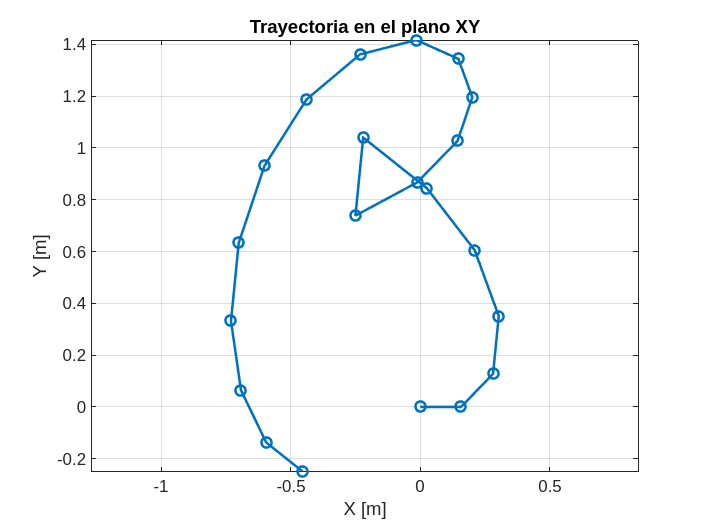


%% Trayectoria estática XY
figure('Name','Trayectoria XY','NumberTitle','off');
plot(x, y,'-o','LineWidth',1.5), axis equal, grid on
xlabel('X [m]'), ylabel('Y [m]'), title('Trayectoria en el plano XY')

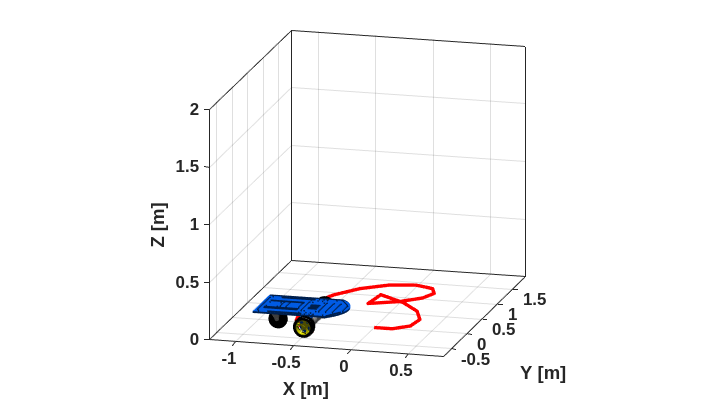


%% ----------------------------------------------------------------------
%% Simulación Virtual 3D (nuevo) — conserva todo lo anterior
%% Simulación Virtual 3D (nuevo) — conserva todo lo anterior
hx = x;  % historial de posiciones X
hy = y;  % historial de posiciones Y

scene = figure('Name','Simulación Virtual 3D','NumberTitle','off');
set(scene,'Color','white');
set(gca,'FontWeight','bold');
sz = get(0,'ScreenSize');
set(scene,'Position',sz);
camlight('headlight');
axis equal; grid on; box on; hold on;
xlabel('X [m]'); ylabel('Y [m]'); zlabel('Z [m]');
view([15 15]);
axis([min(hx)-0.5, max(hx)+0.5, min(hy)-0.5, max(hy)+0.5, 0, 2]);

% Carga del modelo 3D y escala
MobileRobot_5;
scale = 4;  % <<< define aquí la escala

% Estado inicial
H3D_robot = MobilePlot_4(hx(1), hy(1), phi(1), scale);
H3D_path  = plot3(hx(1), hy(1), 0, 'r', 'LineWidth', 2);

for k = 2:N
    delete(H3D_robot);
    set(H3D_path, 'XData', hx(1:k), 'YData', hy(1:k), 'ZData', zeros(1,k));
    H3D_robot = MobilePlot_4(hx(k), hy(k), phi(k), scale);
    pause(dt);
end